W_100_Heights = reshape(cell2mat(WHITE_100_Heights(:,3)),[],15);
W_100_H0_H6 = [WHITE{10,3}; W_100_Heights];
AS_wavelengths = [410, 440, 470, 510, 550, 583, 620, 670];
VEML_wavelengths = [650, 550, 450];

% plot(AS_wavelengths,W_100_H0_H6(1,1:8))
% hold on
% for i = 2:6
%     plot(AS_wavelengths,W_100_H0_H6(i,1:8))
% end
% hold off

% distances = flip([0, 4, 7.8, 11.5, 14.5, 17.5, 20.5]);

% plot(distances,W_100_H0_H6(:,3))
% hold on
% for i = 2:9
%     plot(distances,W_100_H0_H6(:,i))
% end
% legend("CH1","CH2","CH3","CH4","CH5","CH6","CH7","CH8","CLEAR")
% hold off

% d = 30:-5:5;
% DIST_2 = reshape(cell2mat(DIST(:,2)),[],15); % integrationtime = 160ms
% DIST_2(:,1);
% plot(d,DIST_2(:,1:9));
% legend("CH1","CH2","CH3","CH4","CH5","CH6","CH7","CH8","CLEAR");
% ax = gca;
% ax.ColorOrder = AS_Colours;
% plot(d,DIST_2(:,11:14));
% legend("Red", "Green", "Blue", "White")
% ax = gca;
% ax.ColorOrder = VEML_Colours;

d = 30:-5:5;
DIST_AS = reshape(cell2mat(DISTas(:,2)),[],15) % integrationtime = 160ms

DIST_AS = 1.0e+04 *

    0.0006    0.0090    0.0087    0.0101    0.0021    0.0046    0.0115    0.0011    0.0272    0.0009    2.2395    2.2395    2.2395    2.2395    0.0080
    0.0008    0.0130    0.0122    0.0144    0.0028    0.0065    0.0153    0.0015    0.0384    0.0013    2.2395    2.2395    2.2395    2.2395    0.0080
    0.0013    0.0201    0.0192    0.0221    0.0042    0.0098    0.0248    0.0023    0.0592    0.0021    2.2395    2.2395    2.2395    2.2395    0.0080
    0.0022    0.0354    0.0359    0.0385    0.0073    0.0174    0.0491    0.0039    0.1040    0.0037    2.2395    2.2395    2.2395    2.2395    0.0080
    0.0050    0.0826    0.0815    0.0897    0.0168    0.0403    0.1107    0.0089    0.2398    0.0086    2.2395    2.2395    2.2395    2.2395    0.0080
    0.0213    0.3546    0.3318    0.3896    0.0700    0.1727    0.4284    0.0383    1.0225    0.0365    2.2395    2.2395    2.2395    2.2395    0.0080


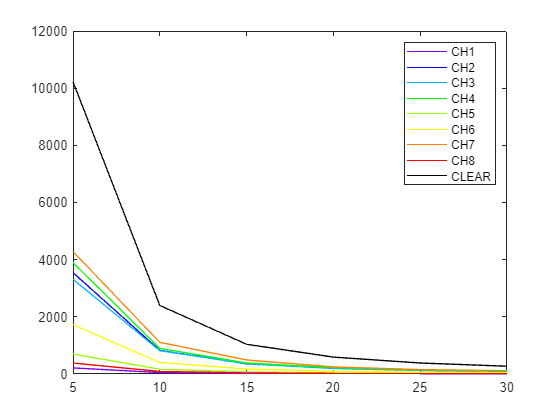

DIST_AS(:,1);
plot(d,DIST_AS(:,1:9));
legend("CH1","CH2","CH3","CH4","CH5","CH6","CH7","CH8","CLEAR");
ax = gca;
ax.ColorOrder = AS_Colours;


DIST_VEML = reshape(cell2mat(DISTveml(:,2)),[],15) % integrationtime = 160ms

DIST_VEML = 1.0e+03 *

         0         0         0         0         0         0         0         0         0         0    0.1103    0.1137    0.1390    0.2106    0.0800
         0         0    0.0010    0.0007         0         0    0.0010         0    0.0010         0    0.1570    0.1629    0.1990    0.2994    0.0800
         0         0         0         0         0         0         0         0         0         0    0.2330    0.2400    0.2990    0.4440    0.0800
         0         0         0         0         0         0         0         0         0         0    0.3870    0.3971    0.5049    0.7387    0.0800
         0         0         0         0         0         0         0         0         0         0    0.7970    0.7973    1.0402    1.5264    0.0800
         0         0         0         0         0         0         0         0         0         0    3.5309    3.5896    4.4386    6.5528    0.0800


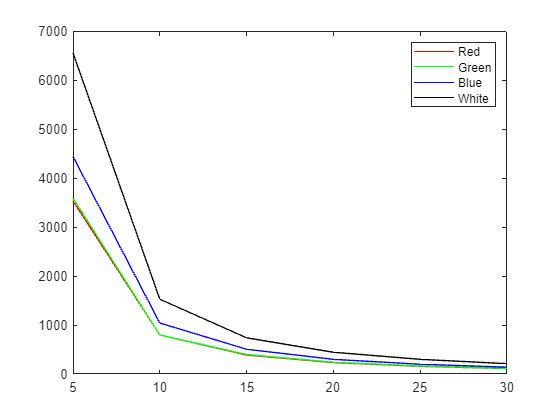

plot(d,DIST_VEML(:,11:14));
legend("Red", "Green", "Blue", "White")
ax = gca;
ax.ColorOrder = VEML_Colours;

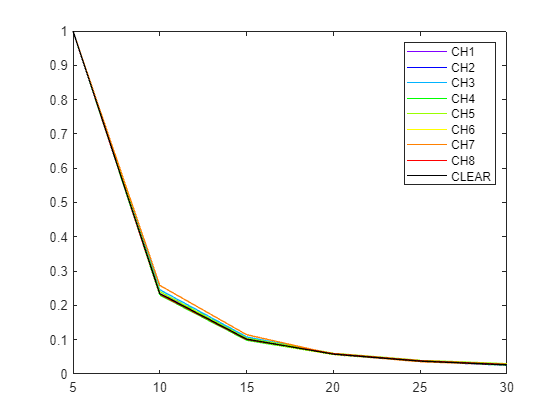

DIST_AS_Normalised = DIST_AS(:,1:9)./DIST_AS(6,1:9);
plot(d,DIST_AS_Normalised(:,1:9));
legend("CH1","CH2","CH3","CH4","CH5","CH6","CH7","CH8","CLEAR");
ax = gca;
ax.ColorOrder = AS_Colours;

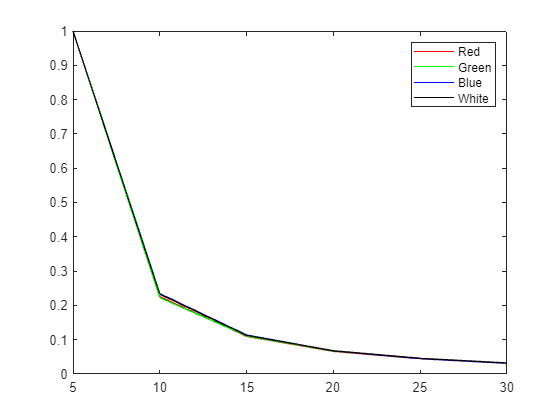


DIST_VEML_Normalised = DIST_VEML(:,11:14)./DIST_VEML(6,11:14); % integrationtime = 160ms
plot(d,DIST_VEML_Normalised(:,:));
legend("Red", "Green", "Blue", "White")
ax = gca;
ax.ColorOrder = VEML_Colours;

function COLOUR_Scaled = scale(COLOUR)
    factors = [4, 2, 1, 0.5, 0.25, 0.125];
    COLOUR_Scaled = cell(6,6);
    for j = 1:10
        for i = 1:6
            COLOUR_Scaled{j,i} = COLOUR{j, i}.*factors(i);
        end
    end
end